clc;
clear;
close all;
format long 

## Set Values

C_piezo = 1e-6;
C_high = 30e-6;
V_high_min = 50;
V_high_max = 105;
V_high = 105;
% V_high = linspace()

## Power Requirement


% P = 

## Piezo control

### DCDC 12 to 103V

#### Capacitors on High Side

C_piezo = 1e-6; %Capacity of piezo in microfarad
C_buffer = 30e-6; %Capacity of buffer capacitors C10 and C11 in parallel in microfarad 
V_high_max_wanted = 100;
Q1_1 = V_high_max_wanted * C_buffer; %Charge when buffer capacitors C10 and C11 are being loaded
Q2_2 = C_piezo/(C_buffer + C_piezo) * Q1_1; %Charge when buffer capacitors C10 and C11 are being unloaded on piezo
V2 = Q2_2 / C_piezo

V2 =   96.774193548387103


V_piezo = sqrt((1/2 * C_high * V_high^2) * 2 / (C_piezo + C_high)) %???

V_piezo =      1.032925691359726e+02


V_piezo = C_high * V_high / (C_piezo + C_high) %- wrong?

V_piezo =      1.016129032258064e+02


#### Resistors for voltage divider 120V

V_measure = 3.3;
V_upper = 100;
R_upper = 100e3;
R_lower = R_upper / (V_upper / V_measure)

R_lower =         3300


R_lower = 2.2e3

R_lower =         2200


P = V_upper^2 / (R_upper + R_lower)

P =    0.097847358121331


R_measure = R_lower; %chosen value to measure voltage with uC
V_ans = V_upper * R_measure / (R_measure + R_upper)

V_ans =    2.152641878669276


V_current = V_ans * (R_measure + R_upper) / R_measure

V_current =    100


% P_upper = 
R_series_voltage_divider = R_upper + R_measure;
I_chosen_divider = V_high / R_series_voltage_divider;
P_chosen_divider = R_series_voltage_divider * I_chosen_divider ^ 2

P_chosen_divider =    0.107876712328767


#### Resistor for minimum resistive load of 10mA

I_high_side = .01;
R_chosen = 5.1e3;
R_max = R_chosen;
% R_max = V_high_max / I_high_side %maximum 9k
R_total_max = (R_series_voltage_divider * R_max) / (R_series_voltage_divider + R_max)

R_total_max =      4.857595526561044e+03


I_total_min = V_high_min / R_total_max %= V_high / R_max + I_chosen_divider 

I_total_min =    0.010293158359234


I_total = V_high_max / R_total_max

I_total =    0.021615632554392


P_max  = I_total^2 * R_total_max

P_max =    2.269641418211120


R_measured = 4.55e3

R_measured =         4550


I_measured = 50 / R_measured

I_measured =    0.010989010989011


P_measured  = I_measured^2 * R_measured

P_measured =    0.549450549450550


#### Potentiometer for Voltage regulation

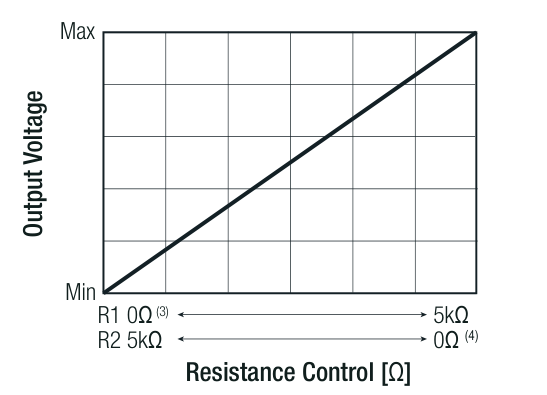

V_low_dc_converter = 50;
V_high_dc_converter = 135;
V_uC = 3.3;
V_dc_converter_max = 4;
Slope = (V_high_dc_converter - V_low_dc_converter) / V_dc_converter_max;
V_out_max = V_low_dc_converter + V_uC * Slope

V_out_max =      1.201250000000000e+02


#### Digital Analot Converter 

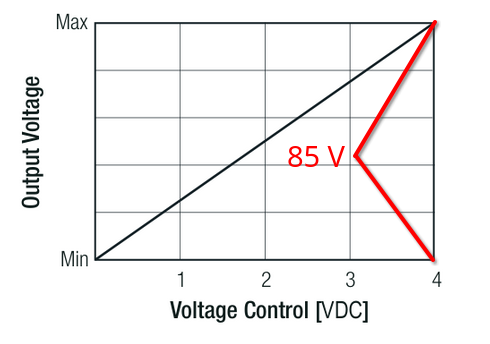

V_low_dc_converter = 50;
V_high_dc_converter = 135;
V_uC = 3.3;
V_dc_converter_max = 4;
Slope = (V_high_dc_converter - V_low_dc_converter) / V_dc_converter_max

Slope =   21.250000000000000


V_out_max = V_low_dc_converter + V_uC * Slope

V_out_max =      1.201250000000000e+02


V_high__max_wanted = 100;
V_Control_max = (V_high__max_wanted - V_low_dc_converter) / Slope 

V_Control_max =    2.352941176470588


V_Control_max = 2.7

V_Control_max =    2.700000000000000


Test = V_low_dc_converter + Slope * V_Control_max

Test =      1.073750000000000e+02


#### Voltage Divider for no higher voltage then 100V

Proportion_DAC_Resistors = (V_uC / V_dc_converter_max)

Proportion_DAC_Resistors =    0.825000000000000


R_DAC_upper = 33e3;
R_DAC_lower = R_DAC_upper / Proportion_DAC_Resistors

R_DAC_lower =        40000


R_DAC_lower = 82e3;
V_dac = V_uC * R_DAC_lower / (R_DAC_lower + R_DAC_upper)

V_dac =    2.353043478260870


V_send_i2c = V_dac * (R_DAC_lower + R_DAC_upper) / R_DAC_lower 

V_send_i2c =    3.300000000000000


V_want_piezo = 100;
V_piezo = (V_want_piezo - 50) / Slope

V_piezo =    2.352941176470588


V_piez = V_piezo / 713.043478260869565217e-3

V_piez =    3.299856527977044


V_send_i2c = 0.66

V_send_i2c =    0.660000000000000


Test = V_low_dc_converter + Slope * V_send_i2c

Test =   64.025000000000006


#### Current Plot

R_pot = linspace(0,5000,256);
R_total = (R_series_voltage_divider .* R_pot) ./ (R_series_voltage_divider + R_pot);
y_V = linspace(V_high_min,V_high_max,256);
x_I_total = y_V ./ R_total;
plot(y_V,x_I_total)

#### Symbolic Solution for a given Current

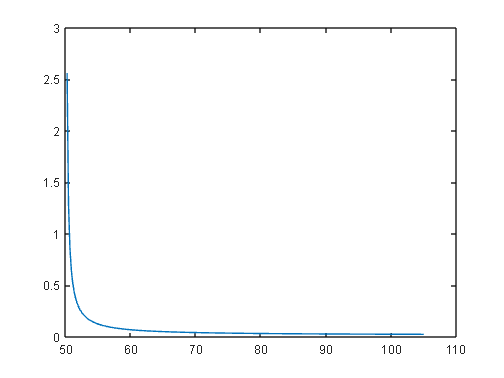

syms R1 R2 R3 R4 V

assume(R1>0 & R2>0 & R3>0 & R4>0 & V>0);
R_ges = (R1 + R2) * (R3 + R4) / ((R1 + R2) + (R3 + R4));
f = V / R_ges;
R2_sol = solve(f == .01, R2,'Real',true)
% R2_sol = isolate(f == .01, R2)


$$R2\_sol = \frac{R_{3}+R_{4}}{\frac{R_{3}+R_{4}}{100\,V}-1}-R_{1}$$

% pretty(simplify(R2_sol,'Steps',50))
x_R2 = subs(R2_sol,[R1, R3, R4], [4120, 88700, 2000])
x_R2 = subs(x_R2,V, y_V);
R2_min = double(x_R2(1))

$$x\_R2 = \frac{90700}{\frac{907}{V}-1}-4120$$

R2_max = double(x_R2(end)) % → choose 10k Poti
R2_steps = linspace(0,1e4,257)

R2_min =      1.171715285880980e+03


plot(y_V,x_R2)

R2_max =      7.754688279301746e+03


#### Current shunt

### HIGH AND LOW SIDE DRIVER 

#### minimum bootstrap capacitor

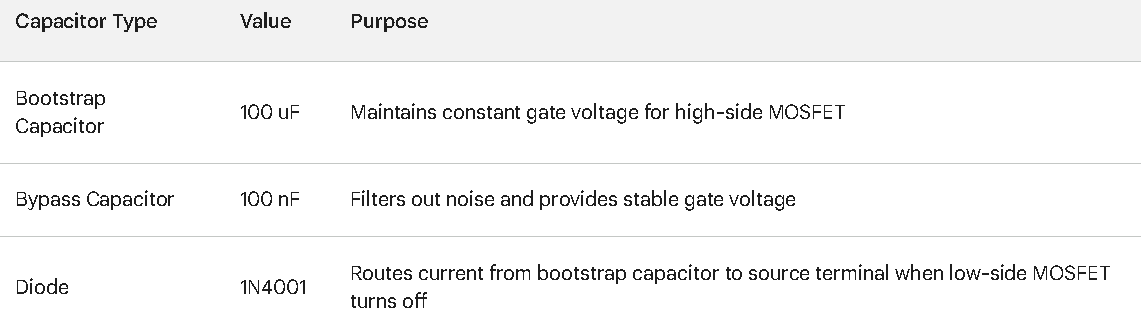

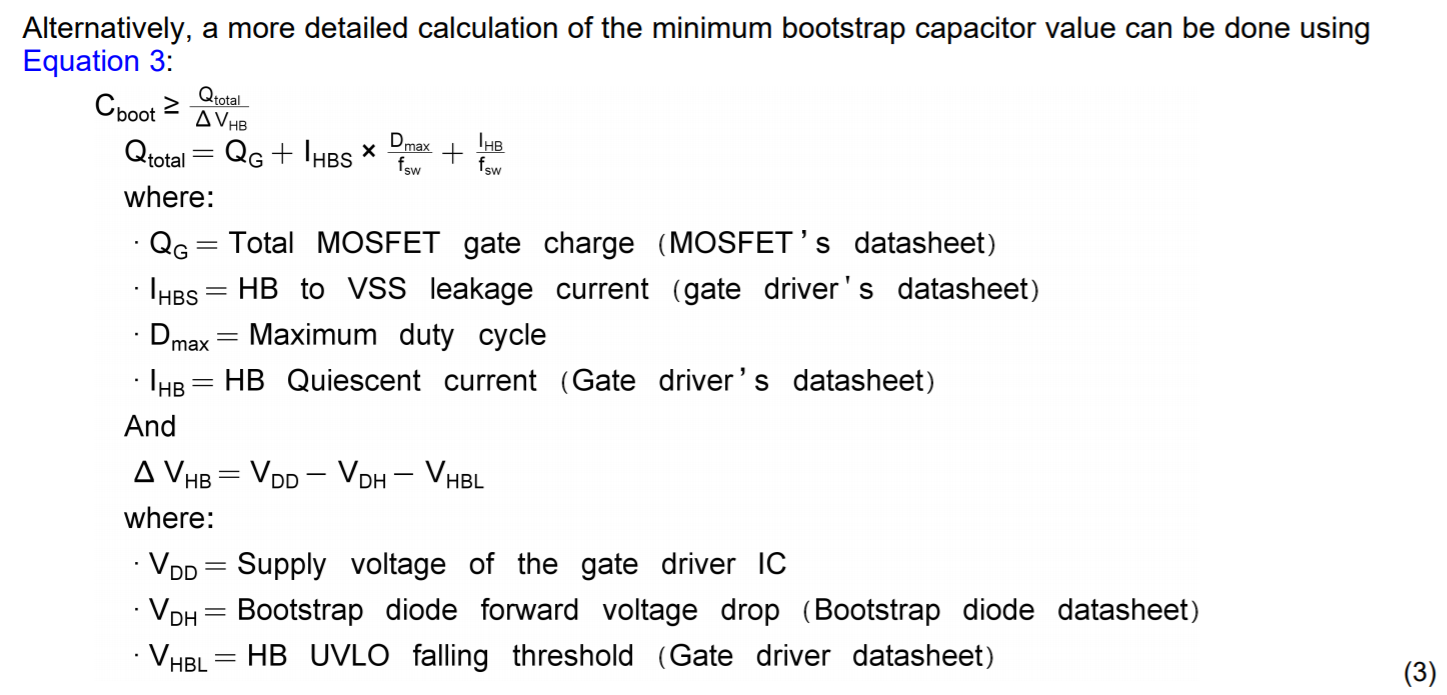

% Q_G = 77e-9;

R2_steps = 1.0e+04 *

                   0   0.003906250000000   0.007812500000000   0.011718750000000   0.015625000000000   0.019531250000000   0.023437500000000   0.027343750000000   0.031250000000000   0.035156250000000   0.039062500000000   0.042968750000000   0.046875000000000   0.050781250000000   0.054687500000000   0.058593750000000   0.062500000000000   0.066406250000000   0.070312500000000   0.074218750000000   0.078125000000000   0.082031250000000   0.085937500000000   0.089843750000000   0.093750000000000   0.097656250000000   0.101562500000000   0.105468750000000   0.109375000000000   0.113281250000000   0.117187500000000   0.121093750000000   0.125000000000000   0.128906250000000   0.132812500000000   0.136718750000000   0.140625000000000   0.144531250000000   0.148437500000000   0.152343750000000   0.156250000000000   0.160156250000000   0.164062500000000   0.167968750000000   0.171875000000000   0.175781250000000   0.179687500000000   0.183593750000000   0.1875000000000

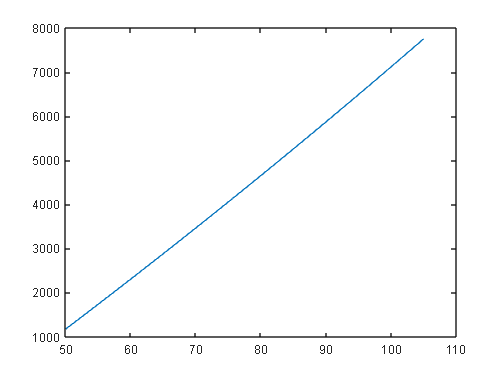

% I_HBS = 170e-6; %= IQBS c current

% I_HB = 1200e-6; %= IQCC Quiescent VCC supply current
% D_max = .02;
% f_sw = 11970;
% Q_total = Q_G + I_HBS + D_max / f_sw + I_HBS / f_sw;
% V_DD = 12;
% V_DH = 1;
% V_HBL = 2.4; % ?
% dV_HB = V_DD - V_DH - V_HBL;
% C_boot = Q_total / dV_HB    


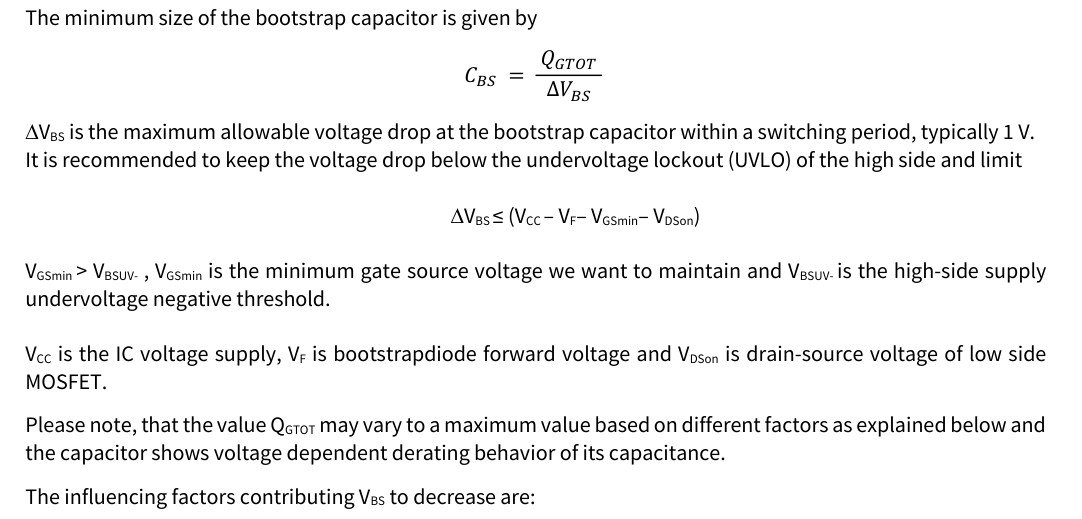

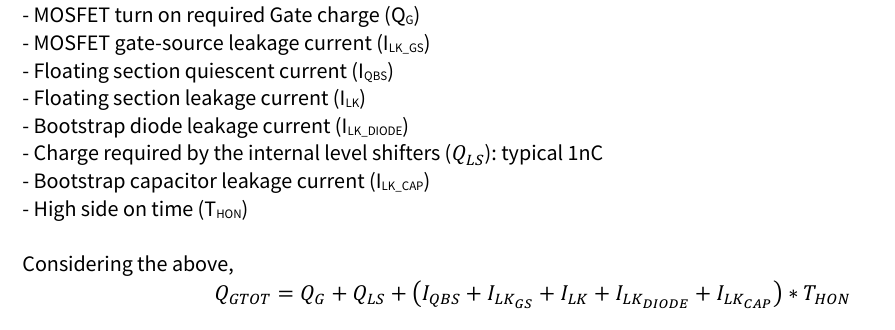

Mosfet: IRFS4115PbF

Gatedriver :Infineon-IRFB4115

Q_G = 77e-9;
Q_LS = 1e-9; %guess
I_QBS = 125e-6; %
I_LKGS = 20e-6; %=Drain-to-Source Leakage Current?
I_LK = 50e-6;
I_LK_DIODE = 1e-6;%guess
I_LK_CAP = 33e-6 * 250  + 10e-6 ; 
T_HON = 0.00002;
Q_total = Q_G + Q_LS + (I_QBS + I_LKGS + I_LK + I_LK_DIODE + I_LK_CAP) * T_HON;
V_CC = 12;
V_F = 1;
V_GSmin = 7;
V_DSon = 3; %??? - drain-source voltage of low side
dV_BS = V_CC -V_F -V_GSmin - V_DSon%typical 1V

dV_BS =      1


C_boot = Q_total / dV_BS 

C_boot =      2.471200000000000e-07


#### Bypass Capacitor

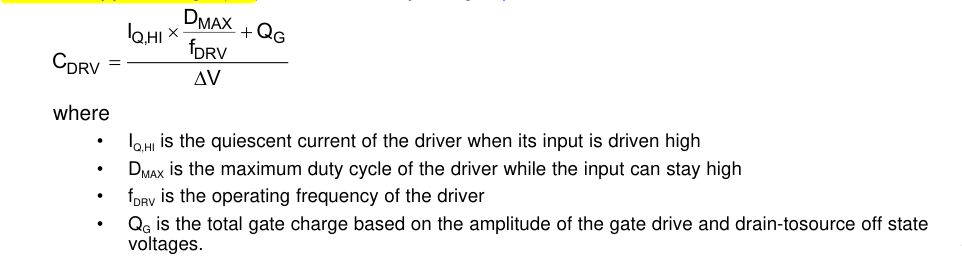

### DCDC 12 to 3.3V

Minimum load 10%

P = 2

P =      2


V = 3

V =      3


P_min = P/10

P_min =    0.200000000000000


I_low_side = P_min / V

I_low_side =    0.066666666666667


R = V / I_low_side 

R =     45


der uC zieht genug Strom dafür